**Stewart Platform IMU Data Processing **

**Author: **Michael Noyce

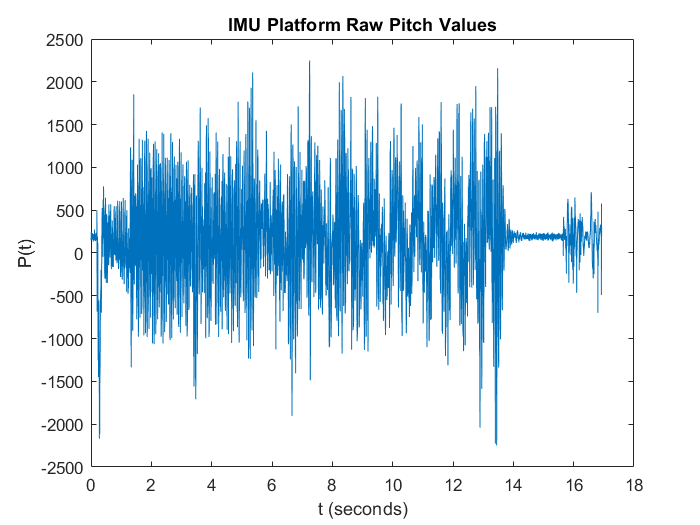

IMUData = readtable('10s_500Hz_20pp_z_axis.csv');
X_acc = IMUData{:, 2};
Y_acc = IMUData{:, 3};
Z_acc = IMUData{:, 4};
roll = IMUData{:, 5};
pitch = IMUData{:, 6};
yaw = IMUData{:, 7};

Fs = 500;            % Sampling frequency                    
T = 1/Fs;             % Sampling period       
L = height(IMUData(:, 4));             % Length of signal
t = (0:L-1)*T;        % Time vector

%X_acc calculations
X_acc_ms2 = X_acc/16381.0; 

X_velocity_uncalibrated = cumtrapz(X_acc_ms2);

X_position_uncalibrated = cumtrapz(X_velocity_uncalibrated);

X_acc_ms2_calibrated = (detrend(X_acc_ms2))/(1669.316);

X_velocity_calibrated = cumtrapz(X_acc_ms2_calibrated);

X_position_calibrated = cumtrapz(X_velocity_calibrated);


%Y_acc calculations
Y_acc_ms2 = Y_acc/16381.0; 

Y_velocity_uncalibrated = cumtrapz(Y_acc_ms2);

Y_position_uncalibrated = cumtrapz(Y_velocity_uncalibrated);

Y_acc_ms2_calibrated = (Y_acc + 42.729)/(1668.9);

Y_velocity_calibrated = cumtrapz(Y_acc_ms2_calibrated);

Y_position_calibrated = cumtrapz(Y_velocity_calibrated);


%Z_acc calculations

Z_acc = lowpass(Z_acc, 10, Fs);

Z_acc_ms2 = Z_acc/16381.0; 

Z_velocity_uncalibrated = cumtrapz(Z_acc_ms2);

Z_position_uncalibrated = cumtrapz(Z_velocity_uncalibrated);

Z_acc_ms2_calibrated = ((Z_acc-92.2236)/(1686.46)) - 9.8172;

Z_velocity_calibrated = cumtrapz((Z_acc_ms2_calibrated));

Z_position_calibrated = cumtrapz((Z_velocity_calibrated));

%Pitch calculations

%pitch = detrend(pitch);

pitch_dps = pitch/131.0; 

pitch_degrees_uncalibrated = cumtrapz(pitch_dps)/360;

pitch_dps_calibrated = (pitch-190.96)/137.32;

pitch_degrees_calibrated = cumtrapz(pitch_dps_calibrated)/360;

%Roll Calculations
roll_dps = pitch/131.0; 

roll_degrees_uncalibrated = cumtrapz(roll_dps)/360;

roll_dps_calibrated = (roll-74.9)/131.226;

roll_degrees_calibrated = cumtrapz(roll_dps_calibrated)/360;

%Yaw Calculations
yaw_dps = pitch/131.0; 

yaw_degrees_uncalibrated = cumtrapz(yaw_dps)/360;

yaw_dps_calibrated = (yaw-20.5908)/145.342;

yaw_degrees_calibrated = cumtrapz(yaw_dps_calibrated)/360;

plot(t, pitch)
title('IMU Platform Raw Pitch Values')
xlabel('t (seconds)')
ylabel('P(t)')

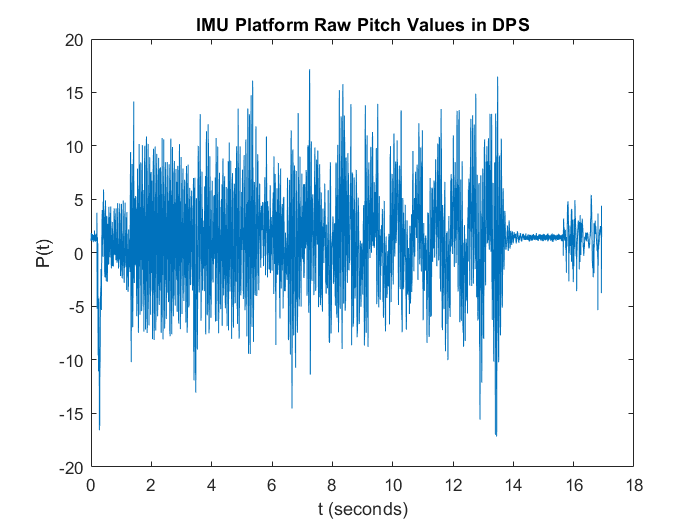


plot(t, pitch_dps)
title('IMU Platform Raw Pitch Values in DPS')
xlabel('t (seconds)')
ylabel('P(t)')

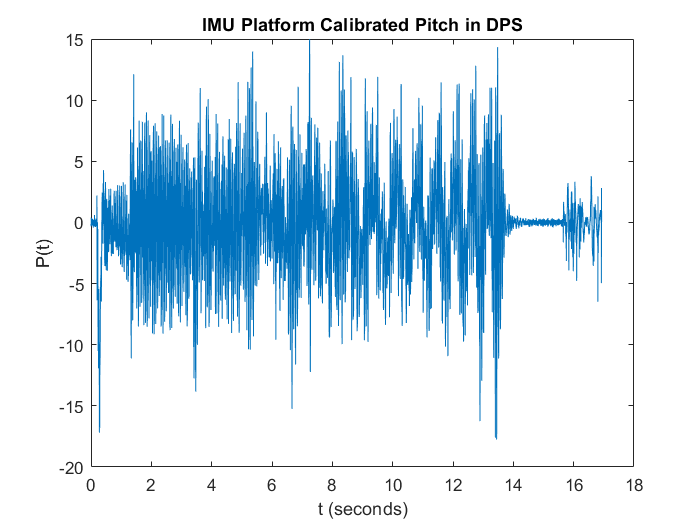


plot(t, pitch_dps_calibrated)
title('IMU Platform Calibrated Pitch in DPS')
xlabel('t (seconds)')
ylabel('P(t)')

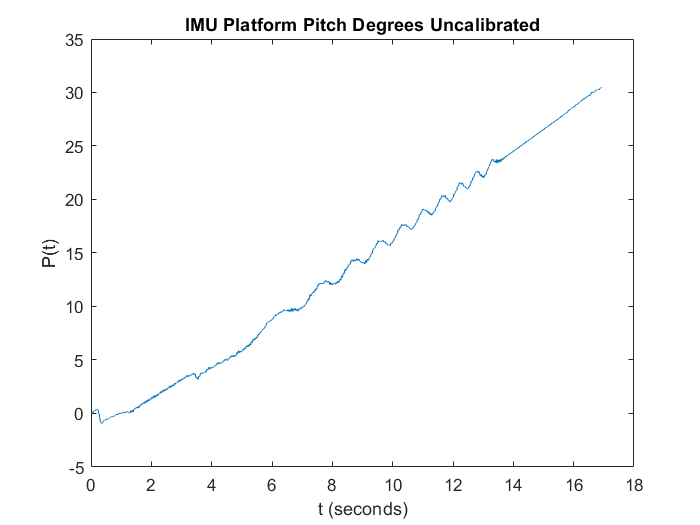


plot(t, pitch_degrees_uncalibrated)
title('IMU Platform Pitch Degrees Uncalibrated')
xlabel('t (seconds)')
ylabel('P(t)')

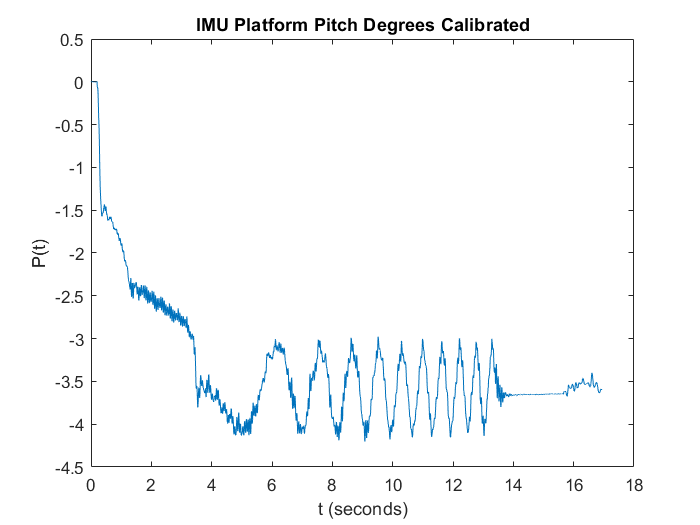


plot(t, pitch_degrees_calibrated)
title('IMU Platform Pitch Degrees Calibrated')
xlabel('t (seconds)')
ylabel('P(t)')

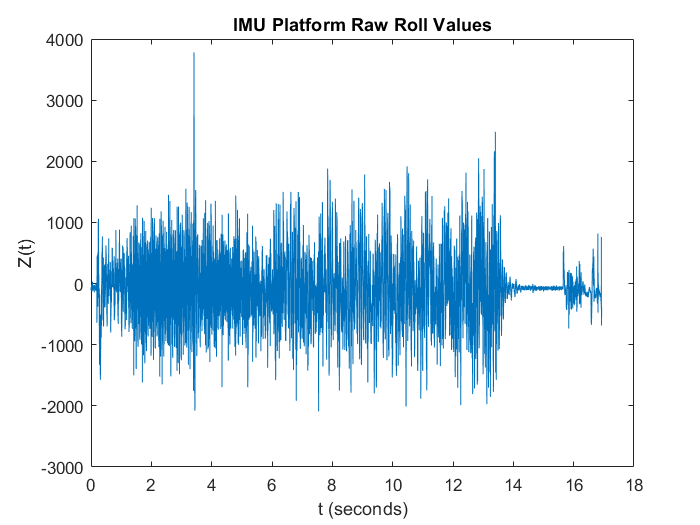



plot(t, roll)
title('IMU Platform Raw Roll Values')
xlabel('t (seconds)')
ylabel('Z(t)')

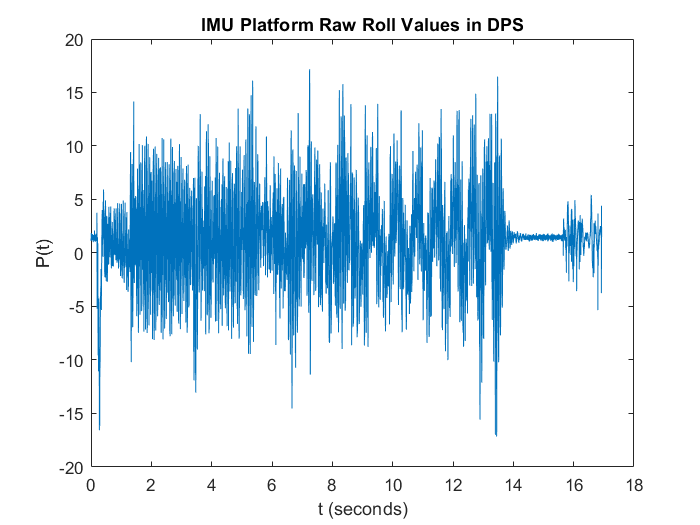


plot(t, roll_dps)
title('IMU Platform Raw Roll Values in DPS')
xlabel('t (seconds)')
ylabel('P(t)')

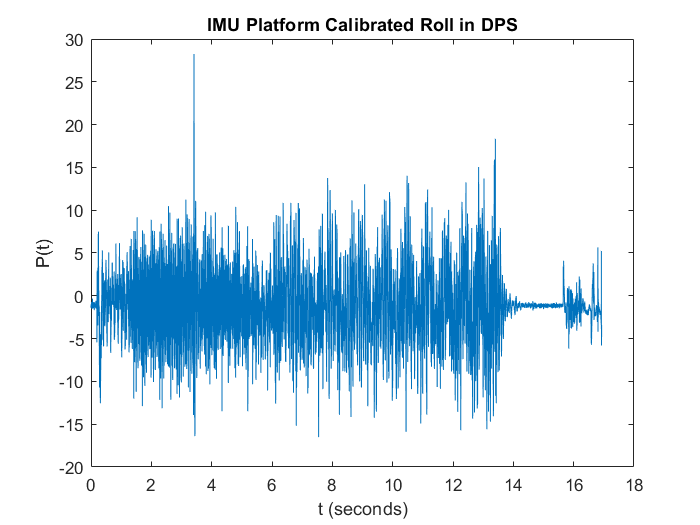


plot(t, roll_dps_calibrated)
title('IMU Platform Calibrated Roll in DPS')
xlabel('t (seconds)')
ylabel('P(t)')

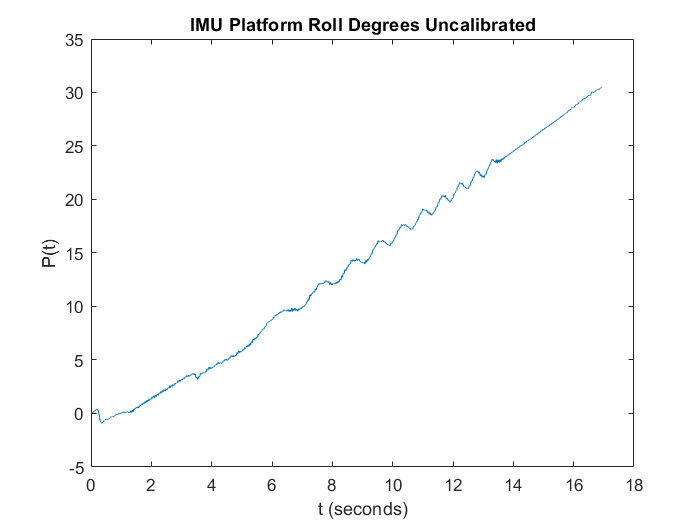


plot(t, roll_degrees_uncalibrated)
title('IMU Platform Roll Degrees Uncalibrated')
xlabel('t (seconds)')
ylabel('P(t)')

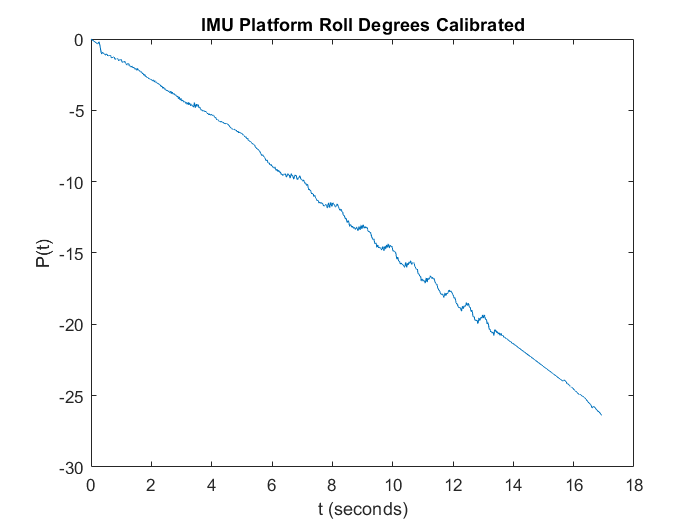


plot(t, roll_degrees_calibrated)
title('IMU Platform Roll Degrees Calibrated')
xlabel('t (seconds)')
ylabel('P(t)')

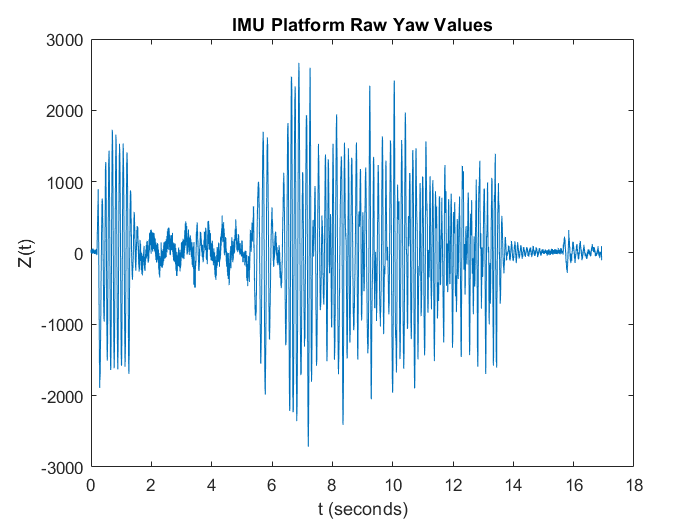


plot(t, yaw)
title('IMU Platform Raw Yaw Values')
xlabel('t (seconds)')
ylabel('Z(t)')

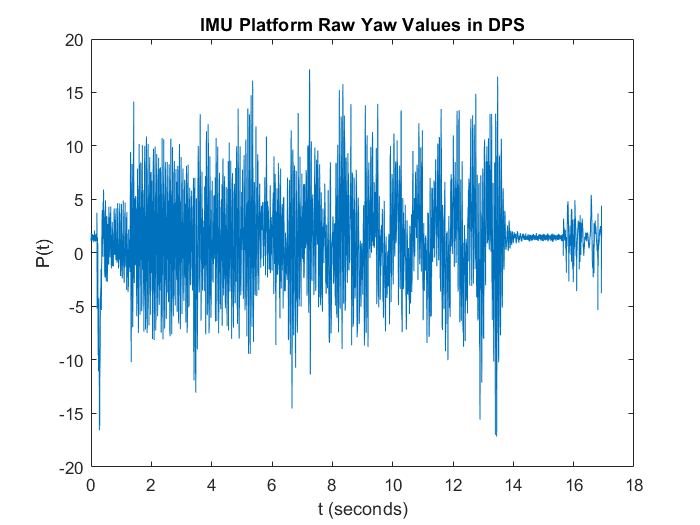


plot(t, yaw_dps)
title('IMU Platform Raw Yaw Values in DPS')
xlabel('t (seconds)')
ylabel('P(t)')

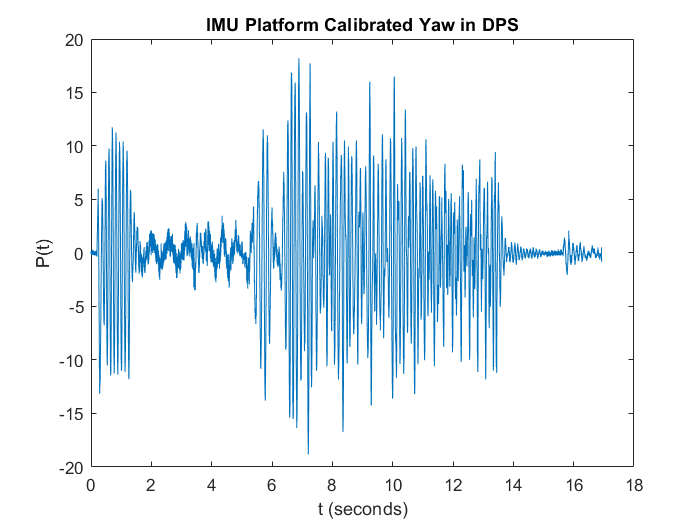


plot(t, yaw_dps_calibrated)
title('IMU Platform Calibrated Yaw in DPS')
xlabel('t (seconds)')
ylabel('P(t)')

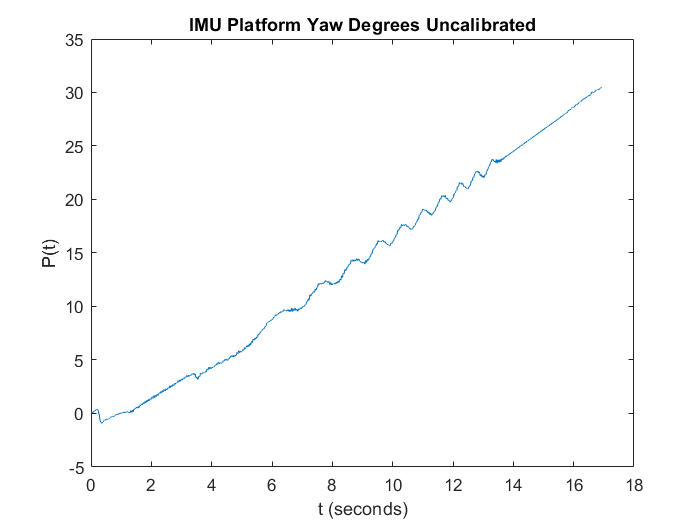


plot(t, yaw_degrees_uncalibrated)
title('IMU Platform Yaw Degrees Uncalibrated')
xlabel('t (seconds)')
ylabel('P(t)')

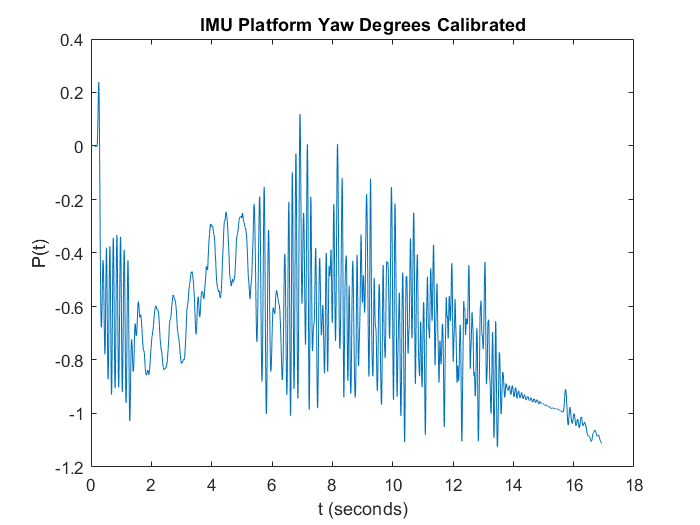


plot(t, yaw_degrees_calibrated)
title('IMU Platform Yaw Degrees Calibrated')
xlabel('t (seconds)')
ylabel('P(t)')

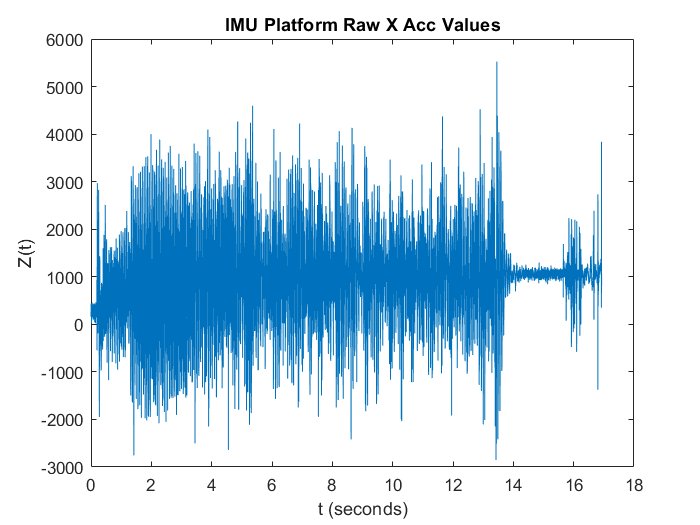



plot(t, X_acc)
title('IMU Platform Raw X Acc Values')
xlabel('t (seconds)')
ylabel('Z(t)')

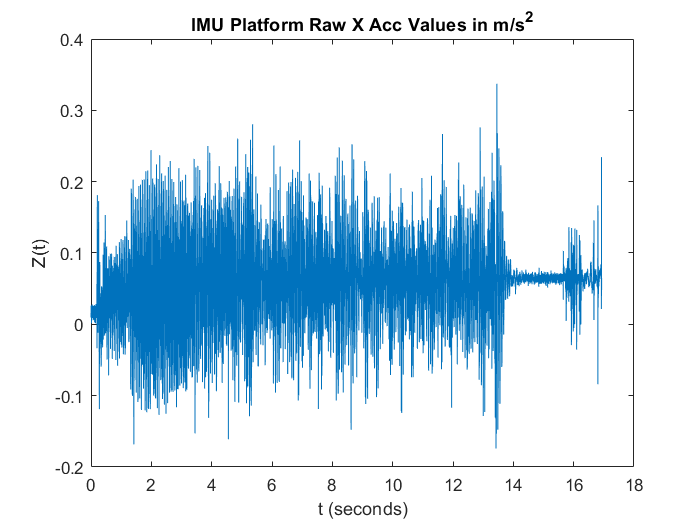


plot(t, X_acc_ms2)
title('IMU Platform Raw X Acc Values in m/s^2')
xlabel('t (seconds)')
ylabel('Z(t)')

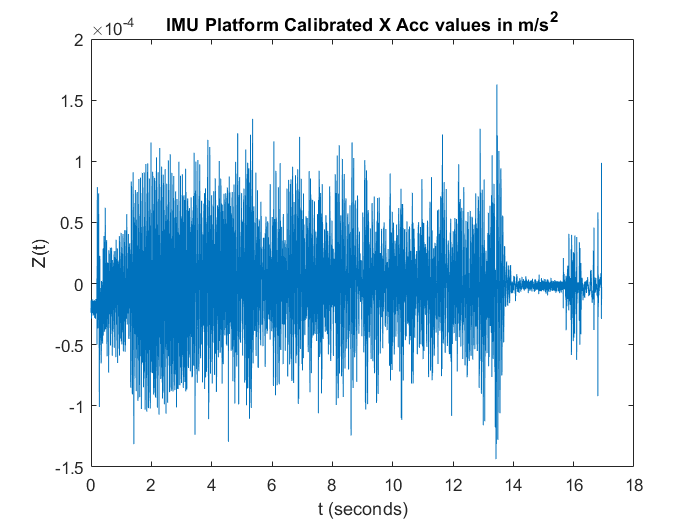


plot(t, X_acc_ms2_calibrated)
title('IMU Platform Calibrated X Acc values in m/s^2')
xlabel('t (seconds)')
ylabel('Z(t)')

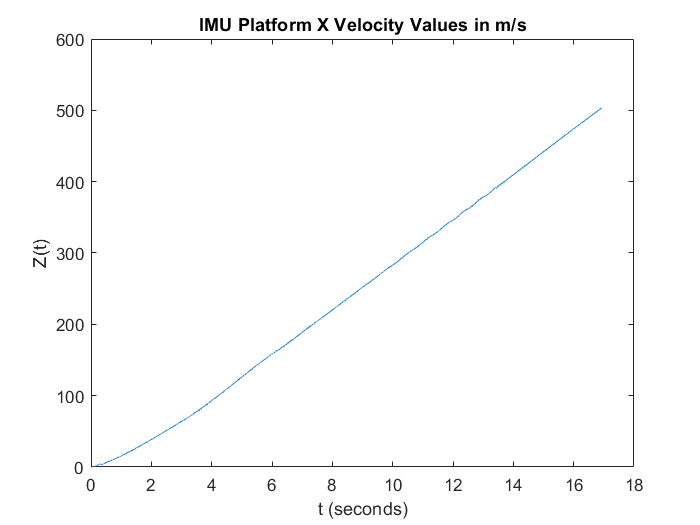


plot(t, X_velocity_uncalibrated)
title('IMU Platform X Velocity Values in m/s')
xlabel('t (seconds)')
ylabel('Z(t)')

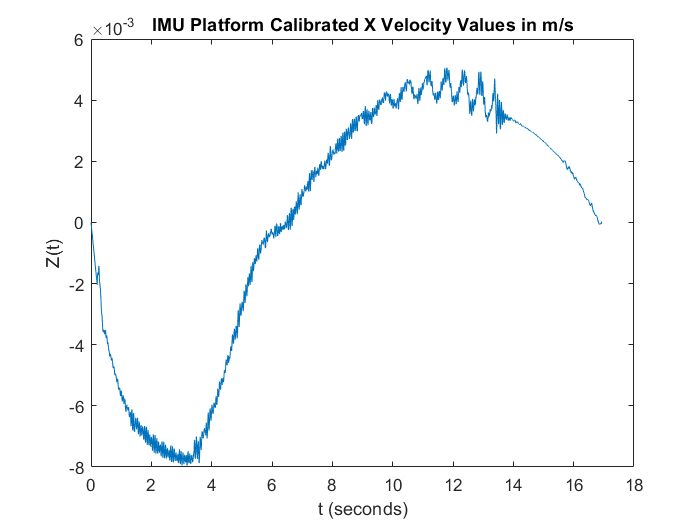


plot(t, X_velocity_calibrated)
title('IMU Platform Calibrated X Velocity Values in m/s')
xlabel('t (seconds)')
ylabel('Z(t)')

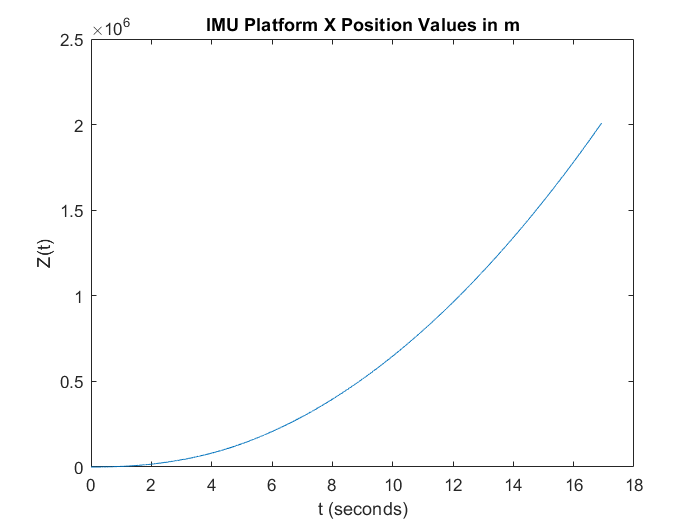


plot(t, X_position_uncalibrated)
title('IMU Platform X Position Values in m')
xlabel('t (seconds)')
ylabel('Z(t)')

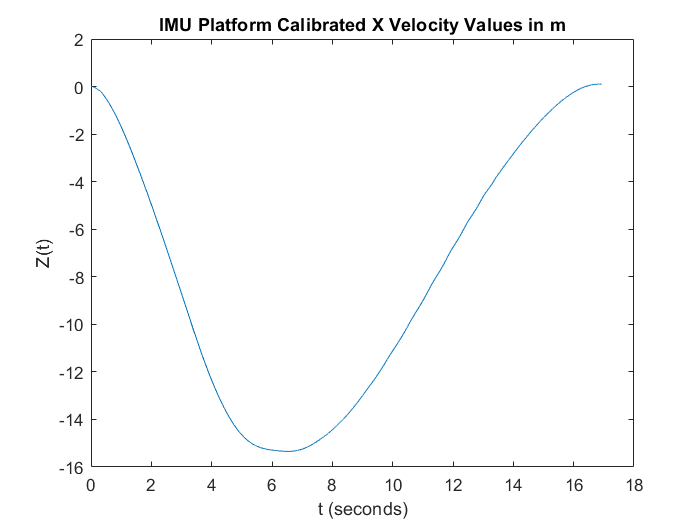


plot(t, X_position_calibrated)
title('IMU Platform Calibrated X Velocity Values in m')
xlabel('t (seconds)')
ylabel('Z(t)')

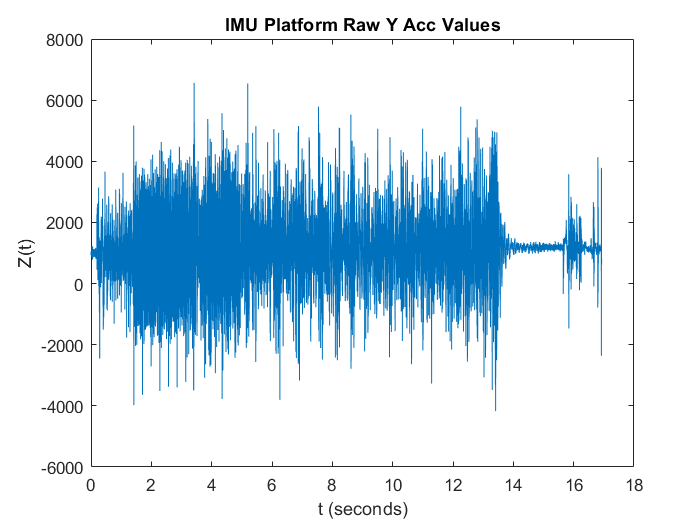


plot(t, Y_acc)
title('IMU Platform Raw Y Acc Values')
xlabel('t (seconds)')
ylabel('Z(t)')

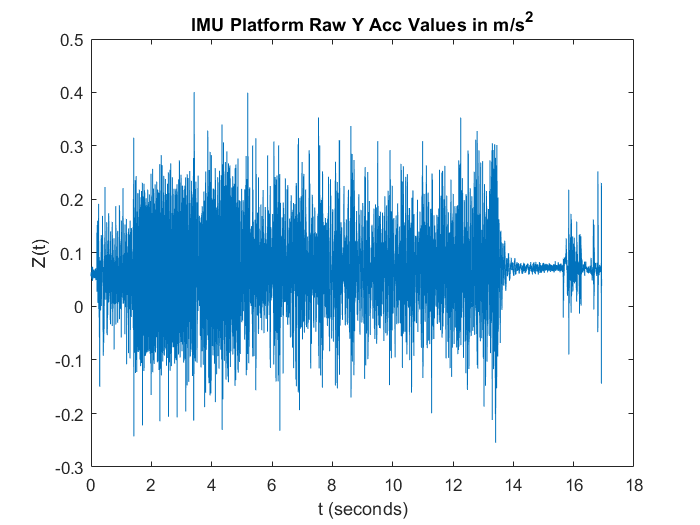


plot(t, Y_acc_ms2)
title('IMU Platform Raw Y Acc Values in m/s^2')
xlabel('t (seconds)')
ylabel('Z(t)')

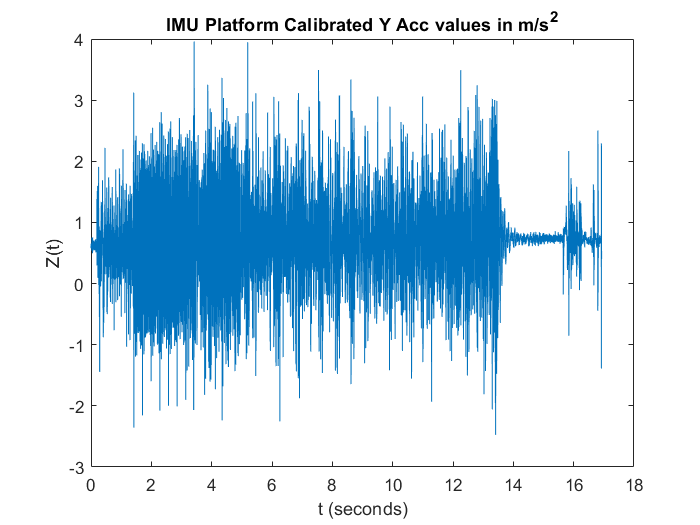


plot(t, Y_acc_ms2_calibrated)
title('IMU Platform Calibrated Y Acc values in m/s^2')
xlabel('t (seconds)')
ylabel('Z(t)')

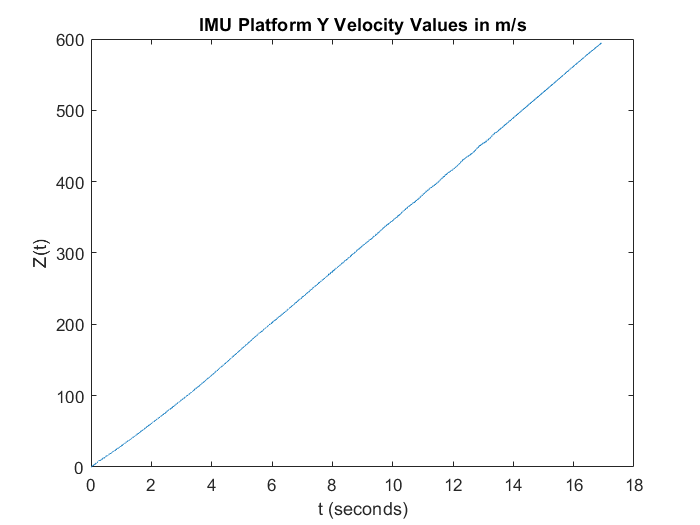


plot(t, Y_velocity_uncalibrated)
title('IMU Platform Y Velocity Values in m/s')
xlabel('t (seconds)')
ylabel('Z(t)')

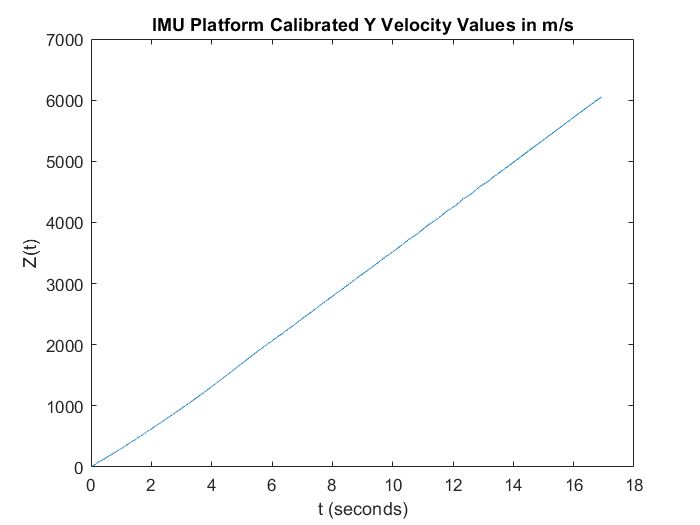


plot(t, Y_velocity_calibrated)
title('IMU Platform Calibrated Y Velocity Values in m/s')
xlabel('t (seconds)')
ylabel('Z(t)')

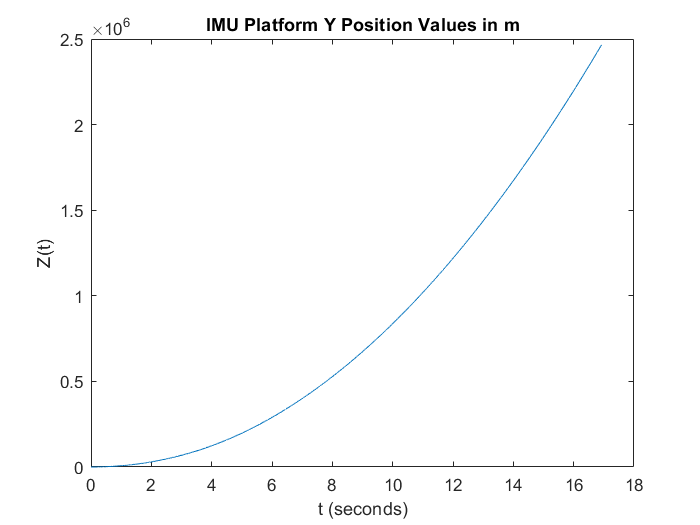


plot(t, Y_position_uncalibrated)
title('IMU Platform Y Position Values in m')
xlabel('t (seconds)')
ylabel('Z(t)')

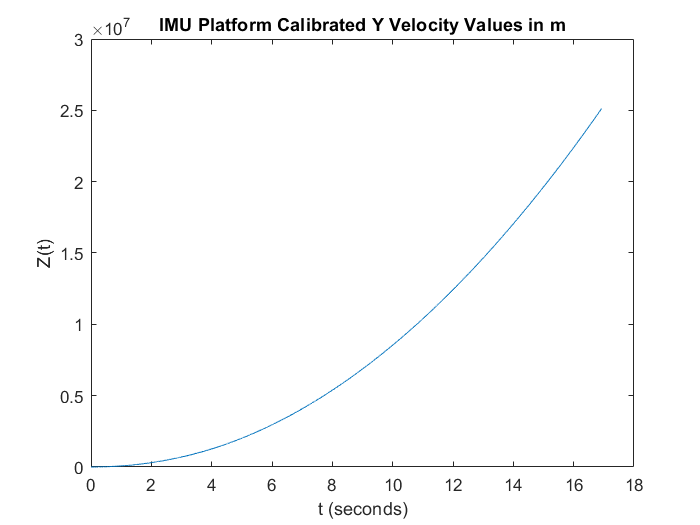


plot(t, Y_position_calibrated)
title('IMU Platform Calibrated Y Velocity Values in m')
xlabel('t (seconds)')
ylabel('Z(t)')

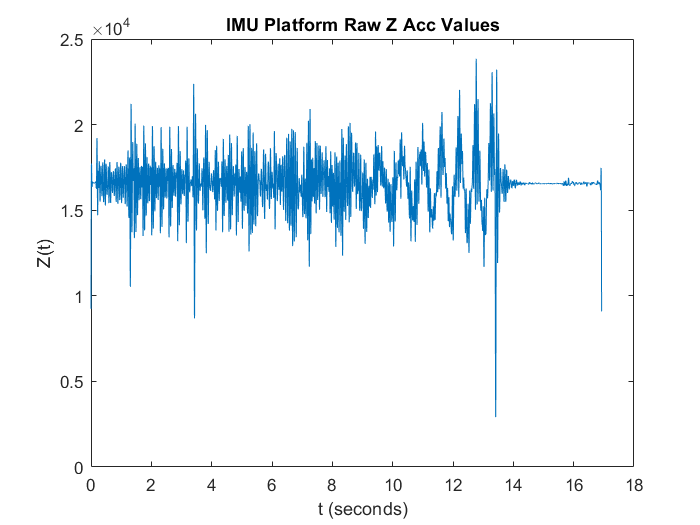



plot(t, Z_acc)
title('IMU Platform Raw Z Acc Values')
xlabel('t (seconds)')
ylabel('Z(t)')

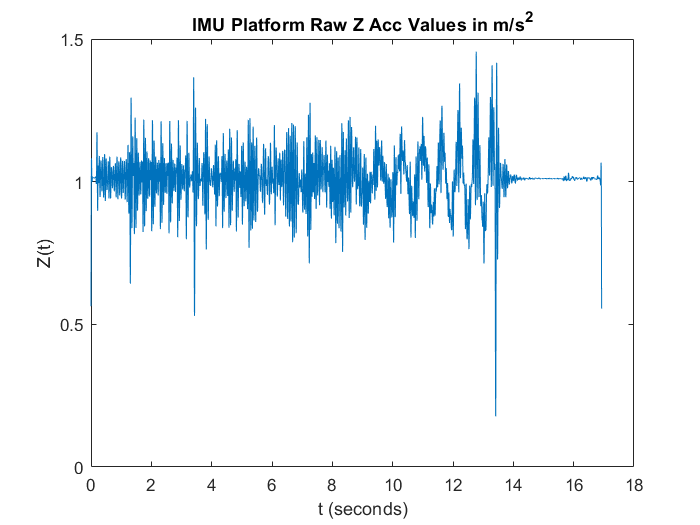


plot(t, Z_acc_ms2)
title('IMU Platform Raw Z Acc Values in m/s^2')
xlabel('t (seconds)')
ylabel('Z(t)')

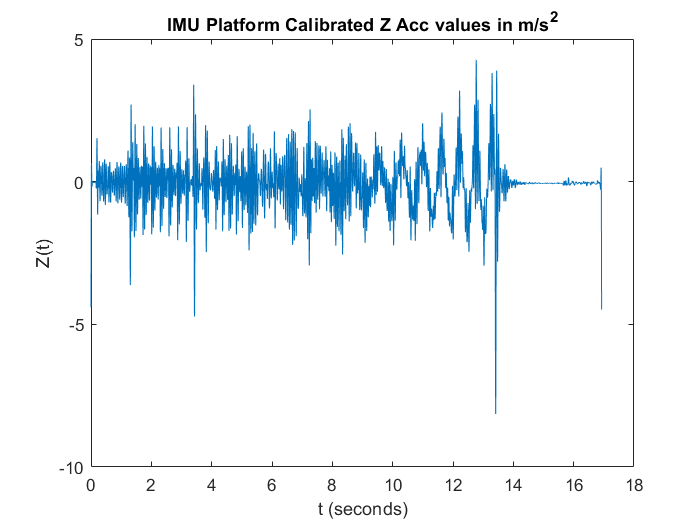


plot(t, Z_acc_ms2_calibrated)
title('IMU Platform Calibrated Z Acc values in m/s^2')
xlabel('t (seconds)')
ylabel('Z(t)')

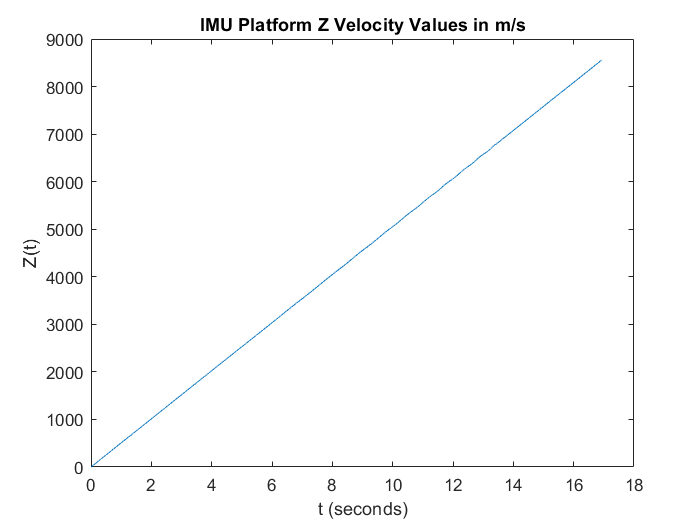


plot(t, Z_velocity_uncalibrated)
title('IMU Platform Z Velocity Values in m/s')
xlabel('t (seconds)')
ylabel('Z(t)')

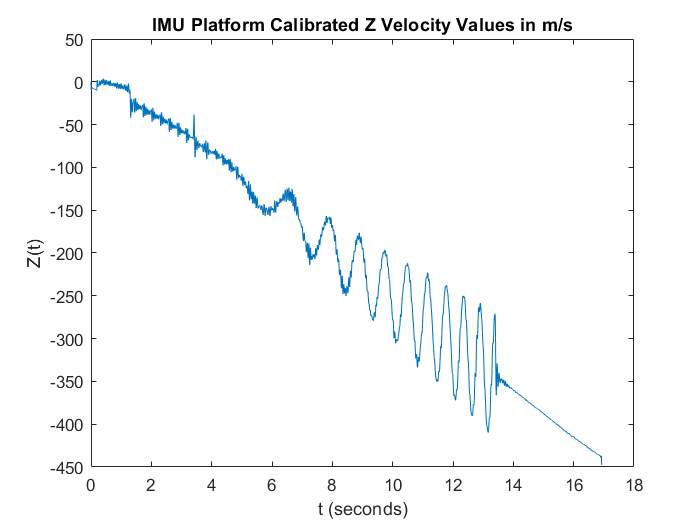


plot(t, Z_velocity_calibrated)
title('IMU Platform Calibrated Z Velocity Values in m/s')
xlabel('t (seconds)')
ylabel('Z(t)')

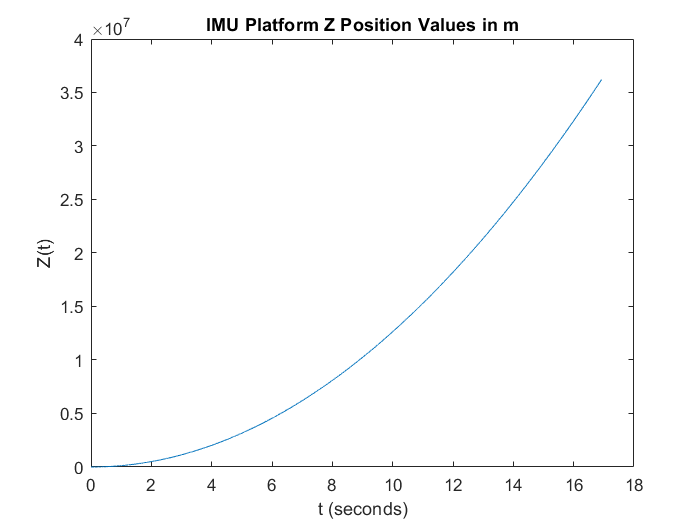


plot(t, Z_position_uncalibrated)
title('IMU Platform Z Position Values in m')
xlabel('t (seconds)')
ylabel('Z(t)')

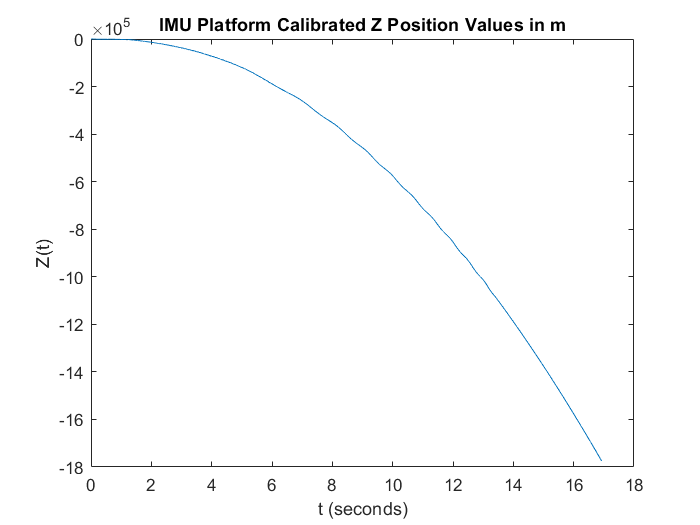


plot(t, Z_position_calibrated)
title('IMU Platform Calibrated Z Position Values in m')
xlabel('t (seconds)')
ylabel('Z(t)')

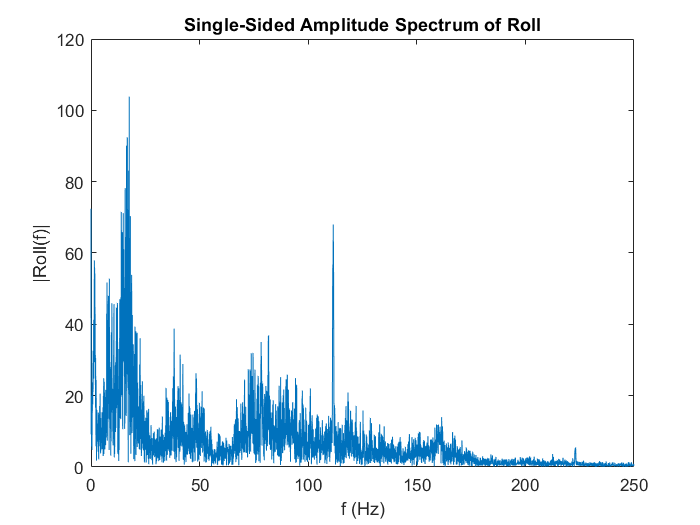



R = fft(roll);
L = length(roll);
P2 = abs(R/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);

f = Fs*(0:(L/2))/L;
plot(f,P1) 
title('Single-Sided Amplitude Spectrum of Roll')
xlabel('f (Hz)')
ylabel('|Roll(f)|')

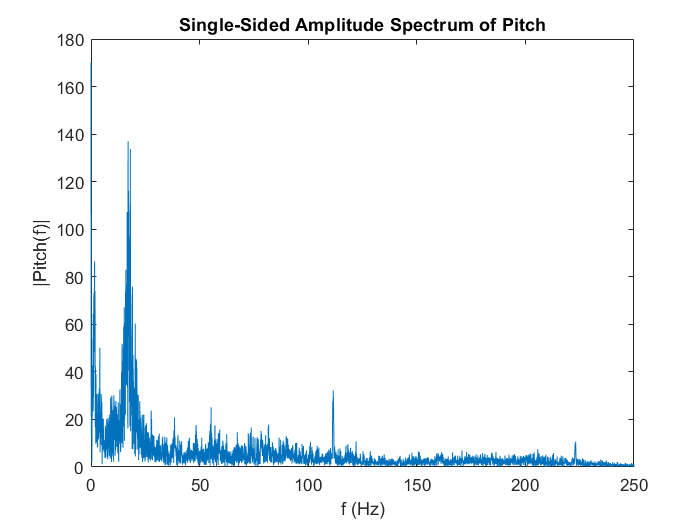


P = fft(pitch);
L = length(pitch);
P2 = abs(P/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);

f = Fs*(0:(L/2))/L;
plot(f,P1) 
title('Single-Sided Amplitude Spectrum of Pitch')
xlabel('f (Hz)')
ylabel('|Pitch(f)|')

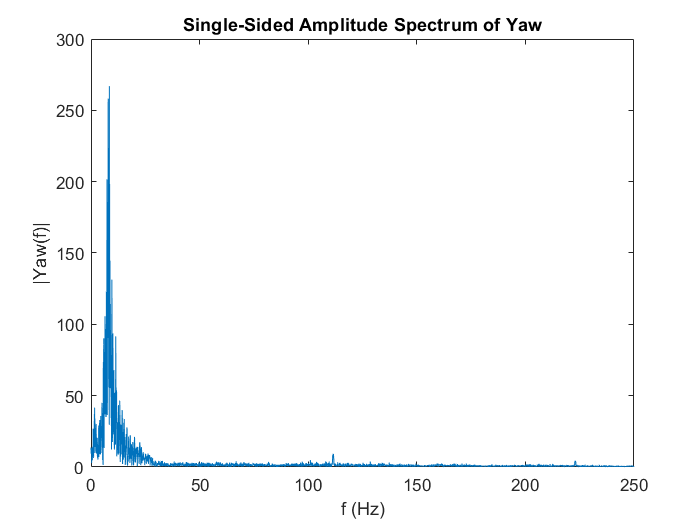


Yaw = fft(yaw);
L = length(yaw);
P2 = abs(Yaw/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);

f = Fs*(0:(L/2))/L;
plot(f,P1) 
title('Single-Sided Amplitude Spectrum of Yaw')
xlabel('f (Hz)')
ylabel('|Yaw(f)|')

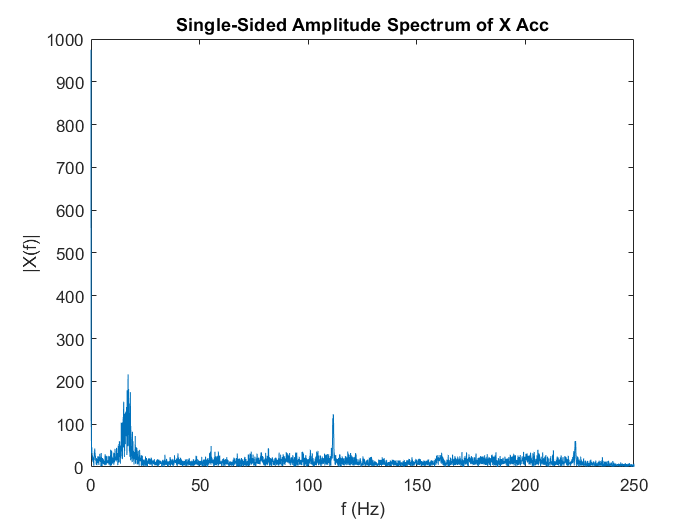


X = fft(X_acc);
L = length(X_acc);
P2 = abs(X/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);

f = Fs*(0:(L/2))/L;
plot(f,P1) 
title('Single-Sided Amplitude Spectrum of X Acc')
xlabel('f (Hz)')
ylabel('|X(f)|')

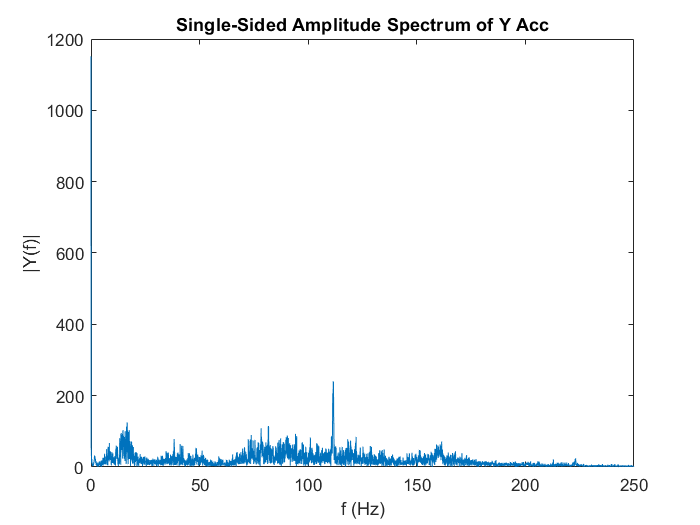


Y = fft(Y_acc);
L = length(Y_acc);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);

f = Fs*(0:(L/2))/L;
plot(f,P1) 
title('Single-Sided Amplitude Spectrum of Y Acc')
xlabel('f (Hz)')
ylabel('|Y(f)|')

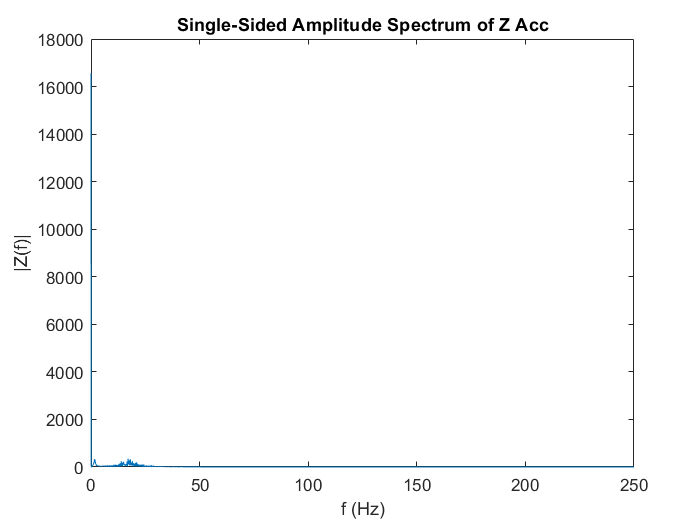


Z = fft(Z_acc);
L = length(Z_acc);
P2 = abs(Z/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);

f = Fs*(0:(L/2))/L;
plot(f,P1) 
title('Single-Sided Amplitude Spectrum of Z Acc')
xlabel('f (Hz)')
ylabel('|Z(f)|')